%% Implementation of the audio soundwaves described in "B. McDermott et al. / Gamma Band Neural Stimulation in Humans and the Promise of a New Modality"
% Uses examples from http://users.jyu.fi/~maarhart/sound-processing-matlab/sound-processing-matlab.html

## Settings:

% General
videoResolutionSize = 64; % 64 x 64
% videoNumberOfCycles = 4;
fs = 48000; % Samples per second
totalDurationSeconds = 5; % Specified in seconds.
t = 0:1/fs:totalDurationSeconds;

%% Frequency Settings:
fc = 440;
fm = 40;

% Note, the period for this is:
period = 0.05; % seconds, at least for s_FAM:

number_periods_to_plot = 4;

## PROBLEM: Notice MAJOR clipping for a reasonable frame rate to sample at!

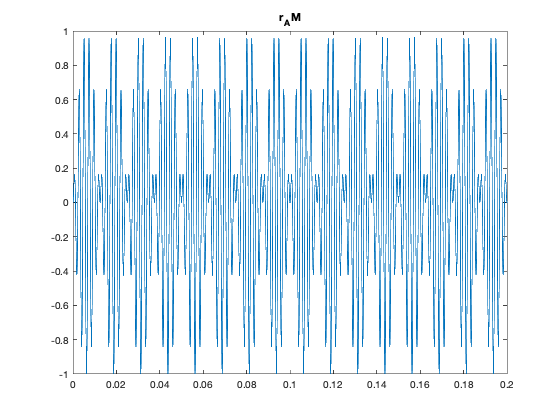


% f = 200;         
% A = .5;      
% w = 0 * pi/180; % degrees 
% y = A * sin(2*pi*f*t + w);
% plot(t,y)
% sound( y, fs, 16 );


%% Simple Sinusoidal AM Tone:
r_AM = sin(2*pi*fc*t).*sin(2*pi*fm*t);
plot(t,r_AM)
title('r_AM')
xlim([0, number_periods_to_plot*period])

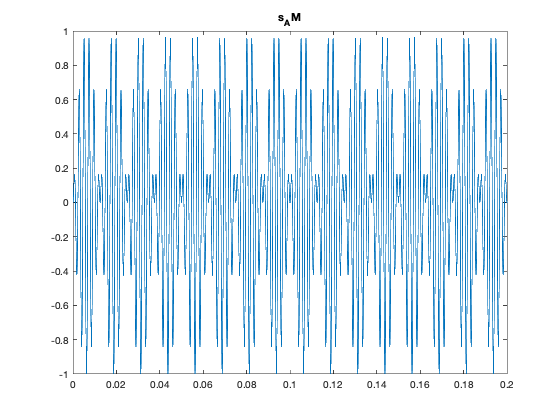



s_AM = AM_Tone(fc, fm, t);
% figure(1)
plot(t,s_AM)
title('s_AM')
xlim([0, number_periods_to_plot*period])

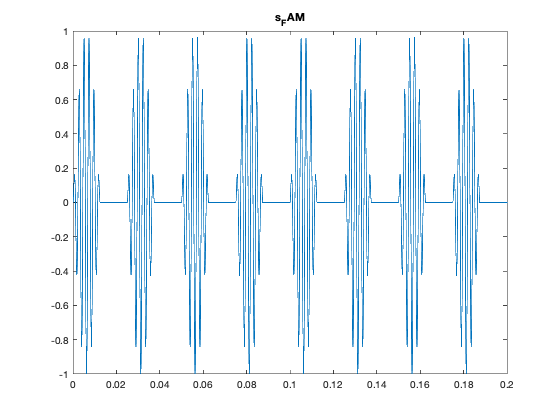

% sound( s_AM, fs, 16 );


%% FAM Tone:
r_FAM = sin(2*pi*fc*t).*sin(2*pi*fm*t).*sin(2*pi*fm*t);
% s(s <= 0) = 0;

s_FAM = FAM_Tone(fc, fm, t);
% figure(2)
plot(t,s_FAM)
title('s_FAM')
xlim([0, number_periods_to_plot*period])

%sound( s_FAM, fs, 16 );

%audiowrite('output/40Hz_FAM.flac', s_FAM, fs)
%[pks,locs] = findpeaks(s_FAM,t)
%period = min(diff(locs))




% Period is 0.0667 seconds
% 0.05 seconds?
% peak_wave_period = max(diff(t(peaks)))

## Create the data:

A = rand(videoResolutionSize);



v = VideoWriter('newfile.avi','Grayscale AVI');
open(v)

% Write the frames:
